m = 10

m = 10

k = 30

k = 30


syms c A1 A2 t

wn = sqrt(2*k / m)

wn = 2.4495


zeta = c/(2*m*wn)

$$zeta = \frac{\sqrt{6}\,c}{120}$$


vpa(solve(1 == c/(2*m*wn), c), 5) / 4 %Dobelt så langt væk så 4x fordi et eller andet er i ^2 

$$ans = 12.247448713915218831971287727356$$

%Eller også sagt, som at x ved demper er 2x af x ved fjeder

x(t) = (A1 + A2 * t)*exp(-wn*t) %%Det er bare som normalt

$$x(t) = {\mathrm{e}}^{-\sqrt{6}\,t}\,\left(A_{1}+A_{2}\,t\right)$$

v(t) = diff(x(t), t)

$$v(t) = A_{2}\,{\mathrm{e}}^{-\sqrt{6}\,t}-\sqrt{6}\,{\mathrm{e}}^{-\sqrt{6}\,t}\,\left(A_{1}+A_{2}\,t\right)$$


[A1 A2] = solve([x(0)==0.25, v(0)==0], [A1, A2]) %

$$A1 = \frac{1}{4}$$

$$A2 = \frac{\sqrt{6}}{4}$$



x(t) = (A1 + A2 * t)*exp(-wn*t)

$$x(t) = {\mathrm{e}}^{-\sqrt{6}\,t}\,\left(\frac{\sqrt{6}\,t}{4}+\frac{1}{4}\right)$$

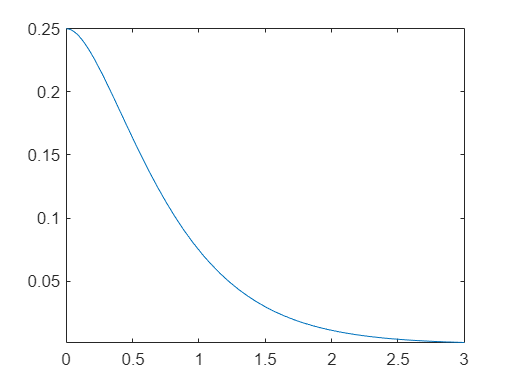

fplot(x(t)) 
xlim([0 3]) 